# Aircraft Dynamics Assignment 8

## William Watkins, Jacob Weiner, Roland Ilyes

## Question 4

Set up workspace

clear
close
clc

Declare constants

global E1 E3 Constants Conv theta0 StabilityFrame A K1 K2 B
B747100Values()

From the work above,

ALin = [StabilityFrame.M.q / E1.Iy, (E1.Velocity * StabilityFrame.M.w) / E1.Iy;
                                 1,                                         0];
Mqnew = 2 * StabilityFrame.M.q; % New Mq with double the pitch stiffness
Mwnew = 2 * StabilityFrame.M.w; % New Mw with double the pitch stiffness
ALinNew = [Mqnew / E1.Iy, (E1.Velocity * Mwnew) / E1.Iy;
                    1,                             0]; % New A matrix for short period approx
[VLin, DLin] = eig(ALin); % Eigenvectors and values of ALin
DLin = diag(DLin);
OmeganLin = sqrt(real(DLin(1))^2 + imag(DLin(1))^2); % Calculating original natural frequency
DampingRatioLin = - real(DLin(1) / OmeganLin); % Calculating the original damping ratio
[VLinNew, DLinNew] = eig(ALinNew); % as above, but for the new Short Period Approximation
DLinNew = diag(DLinNew);
OmeganLinNew = sqrt(real(DLinNew(1))^2 + imag(DLinNew(1))^2);
DampingRatioLinNew = - real(DLinNew(1) / OmeganLinNew);

## Question 2

Create the B matrix for Linearized model

B = [E3.X.deltae / E1.m, E3.Z.deltae / (E1.m - E3.Z.wDot), ...
    (E3.M.deltae / E1.Iy) + ((E3.M.wDot * E3.Z.deltae) / (E1.Iy * (E1.m - E3.Z.wDot))), 0;
                      0,                                0,                                                                                  0, 0]';

## Question 3

### Part a

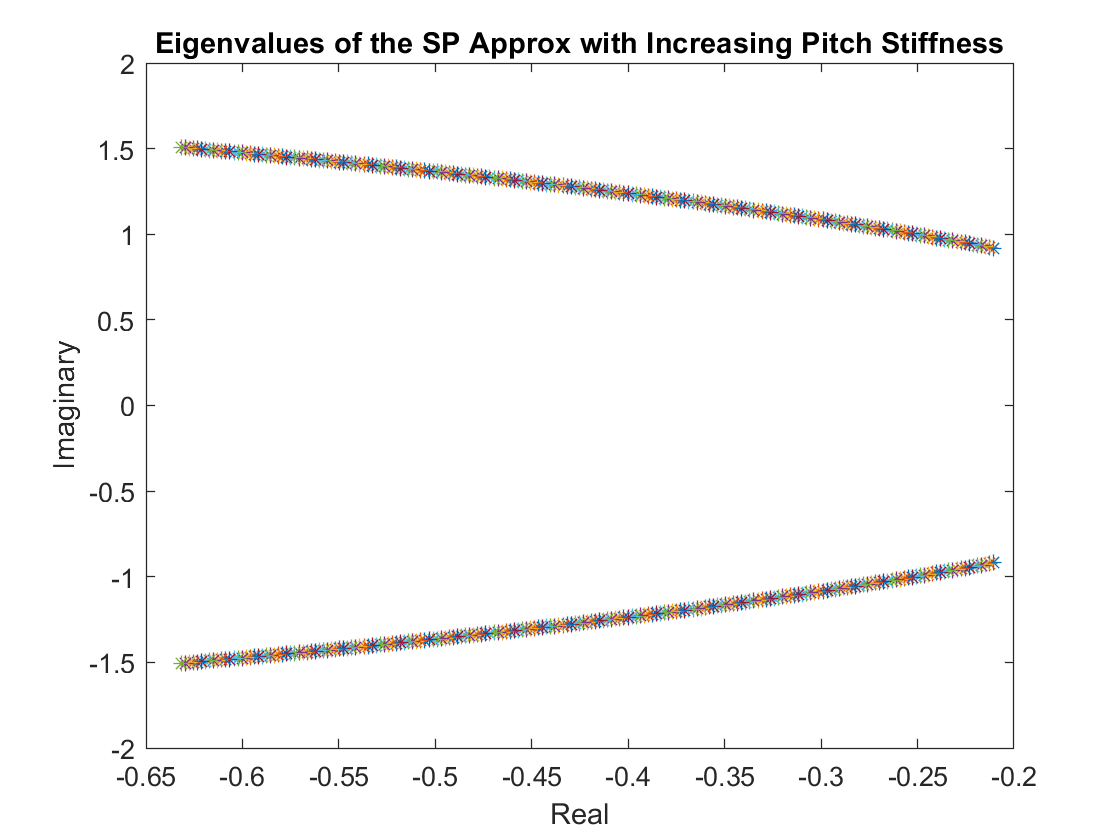

Ks = 1:0.01:3; % Variable Scale Factor ks for pitch stiffness
figure()
for i = Ks
    K1 = (StabilityFrame.M.q / E3.M.deltae) * (-i + 1); % Calculate the K1 for each Ks
    K2 = (E1.Velocity * StabilityFrame.M.w / E3.M.deltae) * (-i + 1); % Calculate K2 
    % for each Ks
    AControl = [(StabilityFrame.M.q / E1.Iy) - (K1 * E3.M.deltae / E1.Iy), ...
        (E1.Velocity * StabilityFrame.M.w / E1.Iy) - (K2 * E3.M.deltae / E1.Iy); 
        1, 0]; % Short Period Approx A Matrix with Controls
    [Vi,Di] = eig(AControl); % Eigenvectors and values
    Di = diag(Di);
    plot(real(Di), imag(Di),'*');
    hold on
end
title('Eigenvalues of the SP Approx with Increasing Pitch Stiffness')
xlabel('Real')
ylabel('Imaginary')
hold off

### Part b

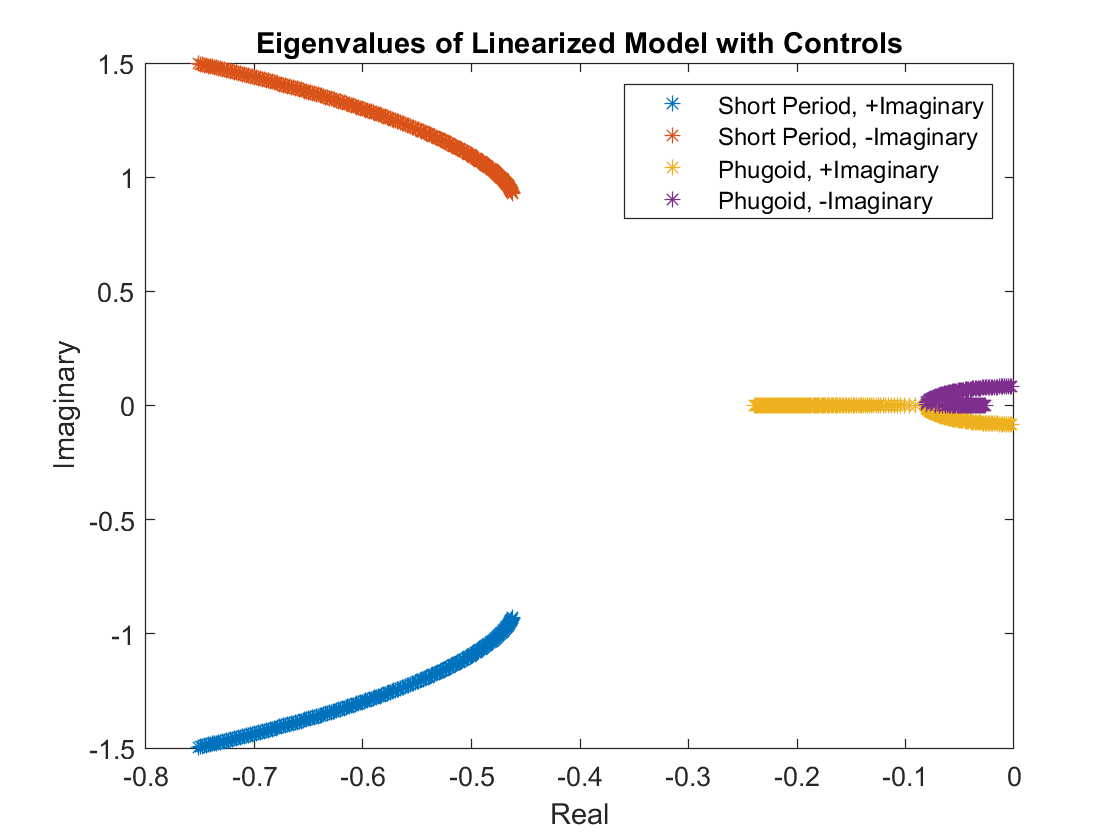

figure()
Ks = 1:0.01:3; % Variable Scale Factor ks for pitch stiffness
k = 0;
for i = Ks
    k = k + 1;
    K1 = (StabilityFrame.M.q / E3.M.deltae) * (-i + 1); % Same thing as above
    K2 = (E1.Velocity * StabilityFrame.M.w / E3.M.deltae) * (-i + 1);
    Asp = [StabilityFrame.M.q / E1.Iy, E1.Velocity * StabilityFrame.M.w / E1. Iy;
           1,                               0]; % Short Period Approx A Matrix w/o controls
    K = [0, 0, K1, K2;
         0, 0,   0,   0]; % Gain Matrix
    ACl = A - B * K; % Calculating the Short Period, Closed Loop A Matrix
    [VLinModel, DLinMod] = eig(ACl); % Eigenvectors, values
    DLinModel(k,:) = diag(DLinMod);
end

DLinModel = sort(DLinModel,2,'ComparisonMethod','real'); % Sorting so that all short period
% Eigenvalues are in columns 1 and 2
plot(real(DLinModel(:,1)), imag(DLinModel(:,1)), '*'); % Plotting Short Period Eigenvalues
hold on
plot(real(DLinModel(:,2)), imag(DLinModel(:,2)), '*');% Plotting Short Period Eigenvalues
plot(real(DLinModel(:,3)), imag(DLinModel(:,3)), '*');% Plotting Phugoid Eigenvalues
plot(real(DLinModel(:,4)), imag(DLinModel(:,4)), '*');% Plotting Phugoid Eigenvalues
legend('Short Period, +Imaginary','Short Period, -Imaginary','Phugoid, +Imaginary',...
    'Phugoid, -Imaginary');
title('Eigenvalues of Linearized Model with Controls')
xlabel('Real')
ylabel('Imaginary')
hold off

### Part c

K1 = 0;
K2 = 0;
K1 = (StabilityFrame.M.q / E3.M.deltae) * (-1 + 1); % K1 for Ks = 1; Hint: It's 0
K2 = (E1.Velocity * StabilityFrame.M.w / E3.M.deltae) * (-1 + 1); K% 2 for Ks = 1 Hint: its 0

K =          0         0   -0.7727   -1.6322
         0         0         0         0


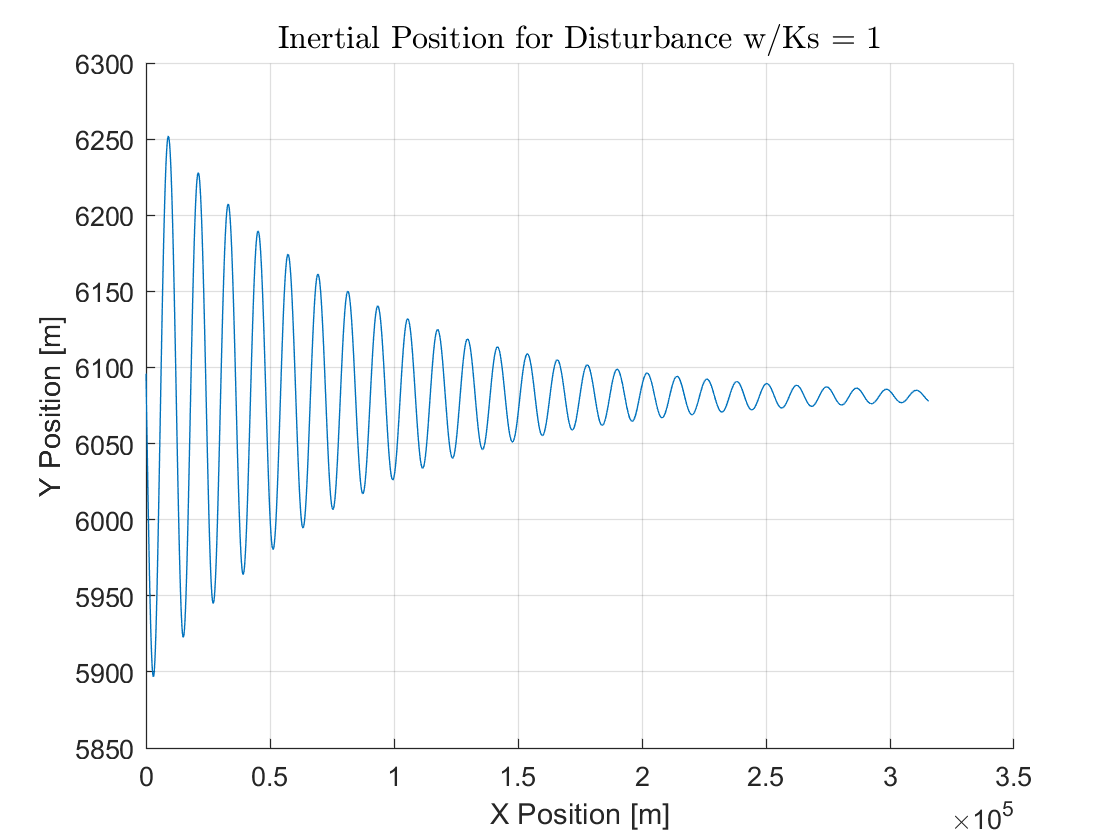

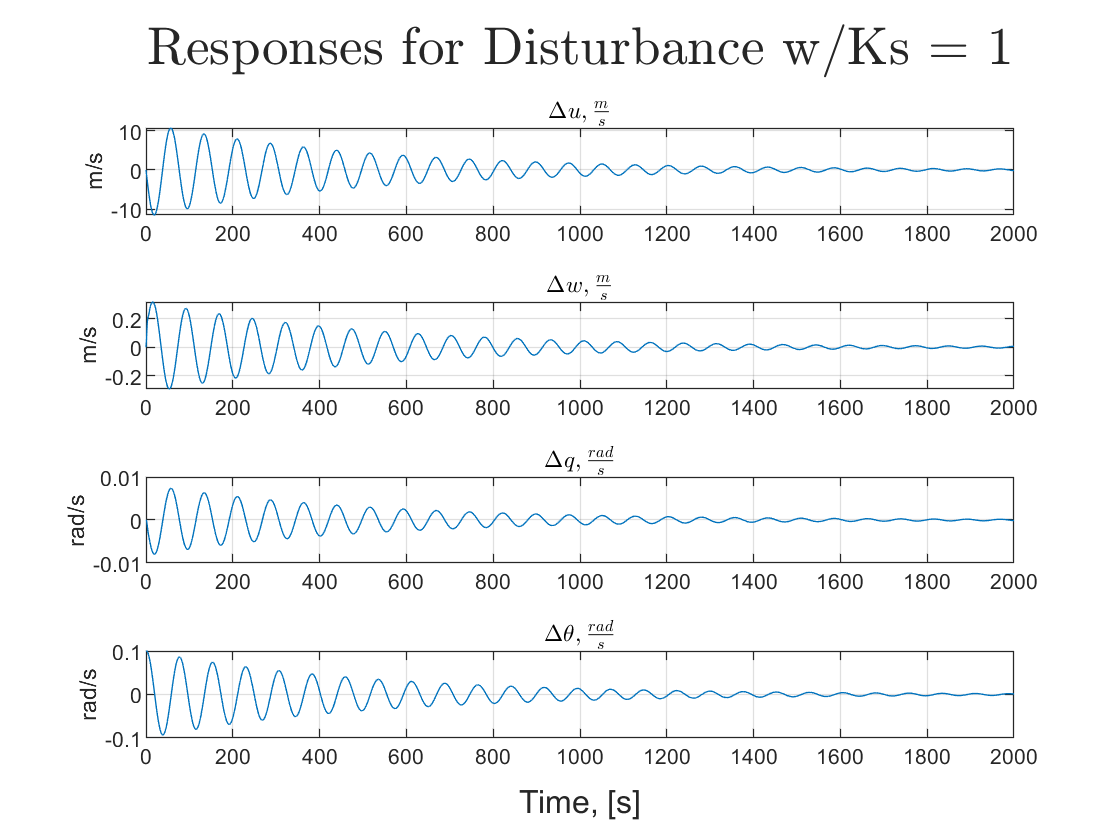


initialDeltauE      = 0; % Change in horizontal velocity
initialDeltavE      = 0; % Change in vertical velocity
initialDeltaq       = 0; % Change in pitch rate
initialDeltaTheta   = 0.1; % Change in pitch
initialDeltaxE      = 0; % Initial X position
initialDeltazE      = E1.Altitude; % Initial altitude

tSpan               = 0:2000; % Setting time span for ODE 45
t = 0;
y = 0;
initial             = [initialDeltauE;
                       initialDeltavE;
                       initialDeltaq;
                       initialDeltaTheta;
                       initialDeltaxE;
                       initialDeltazE]; % Initial State vector

[t, y] = ode45(@(t, y) AirplaneLinearized(t, y, A), tSpan, initial);
 
plutter(t, y, 'Disturbance w/Ks = 1')

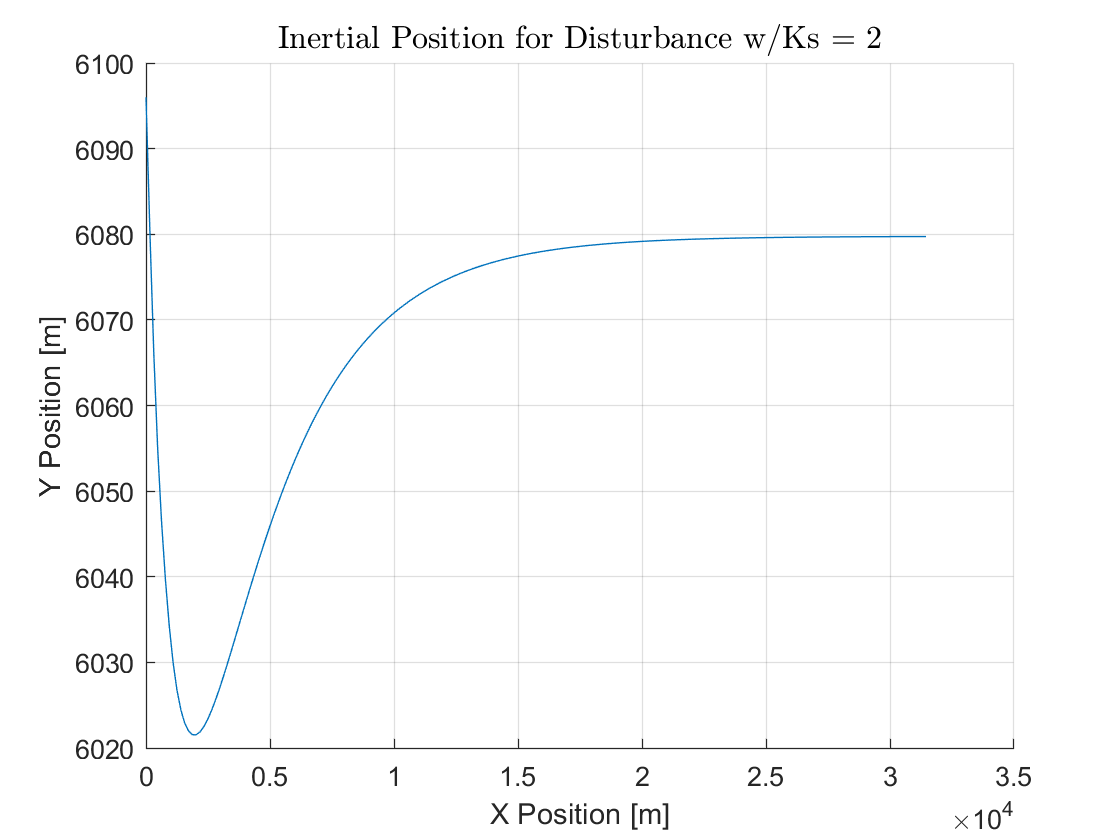

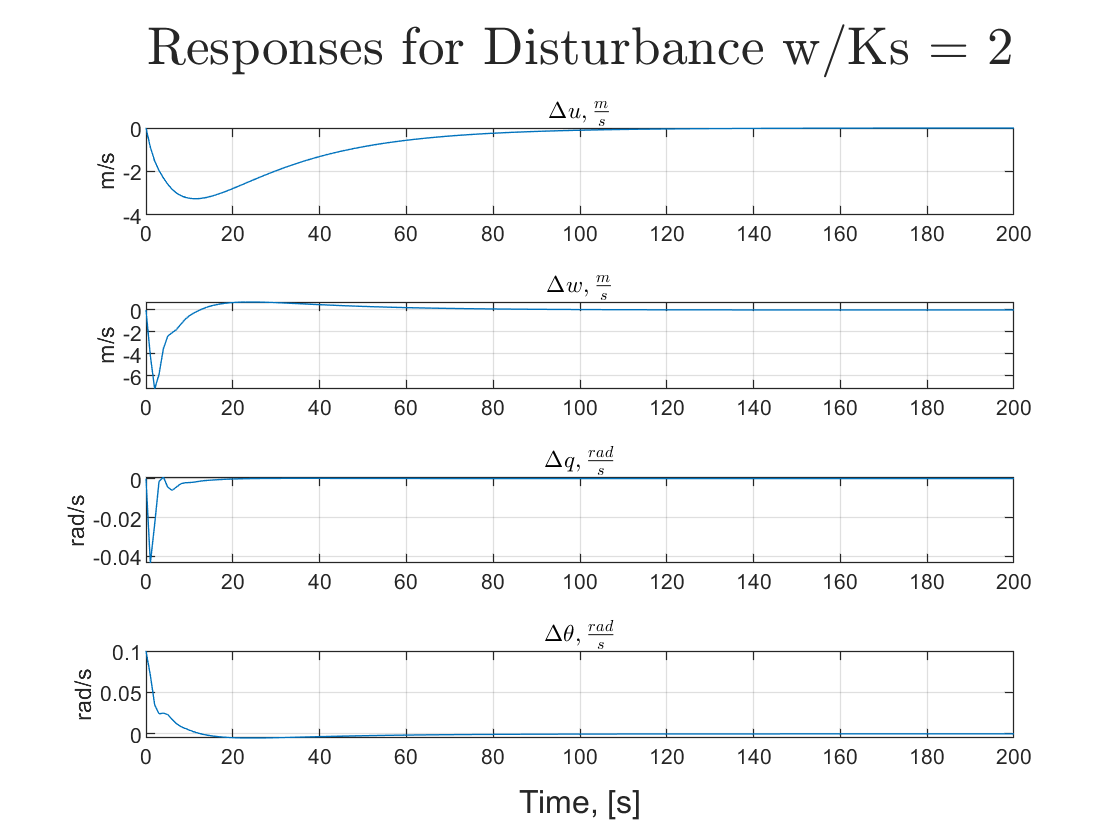

t = 0;
y = 0;

tSpan = 0:200;
K1 = (StabilityFrame.M.q / E3.M.deltae) * (-2 + 1); % K1 for Ks = 2
K2 = (E1.Velocity * StabilityFrame.M.w / E3.M.deltae) * (-2 + 1); % K2 for Ks = 2

[t, y] = ode45(@(t, y) AirplaneLinearized(t, y, A), tSpan, initial);
 
plutter(t, y, 'Disturbance w/Ks = 2')

t = 0;
y = 0;

### Part d

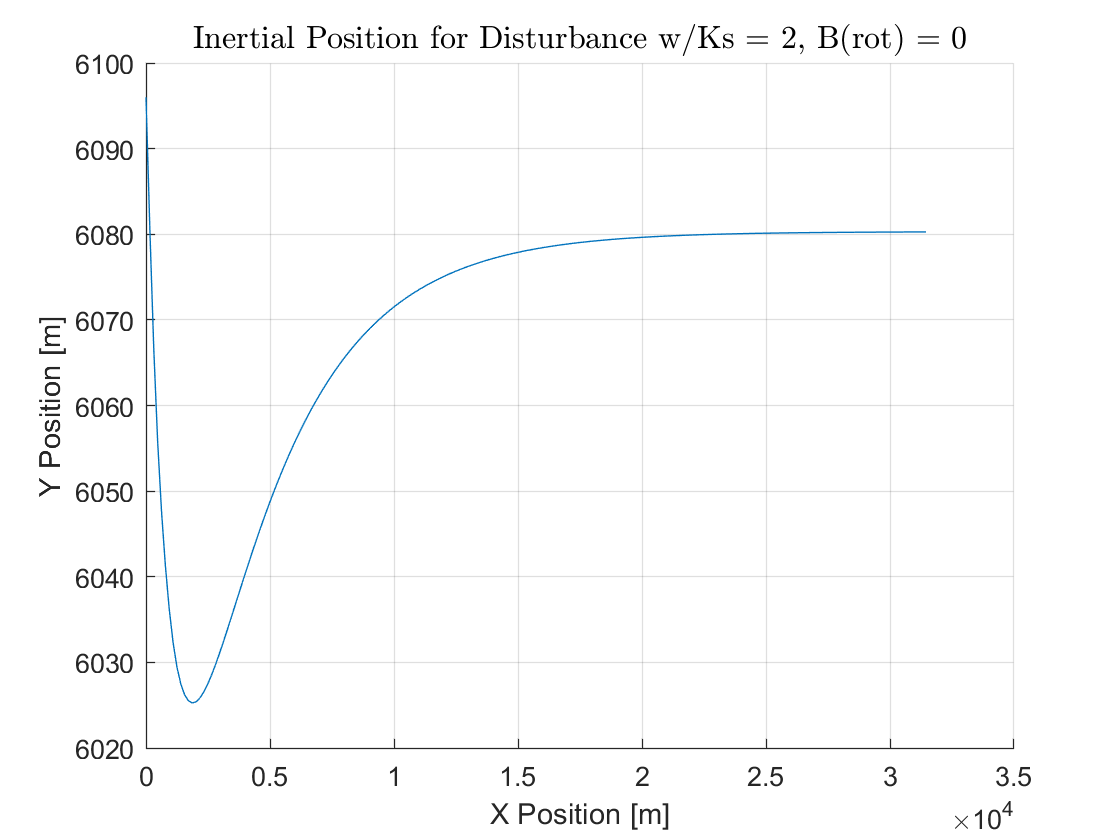

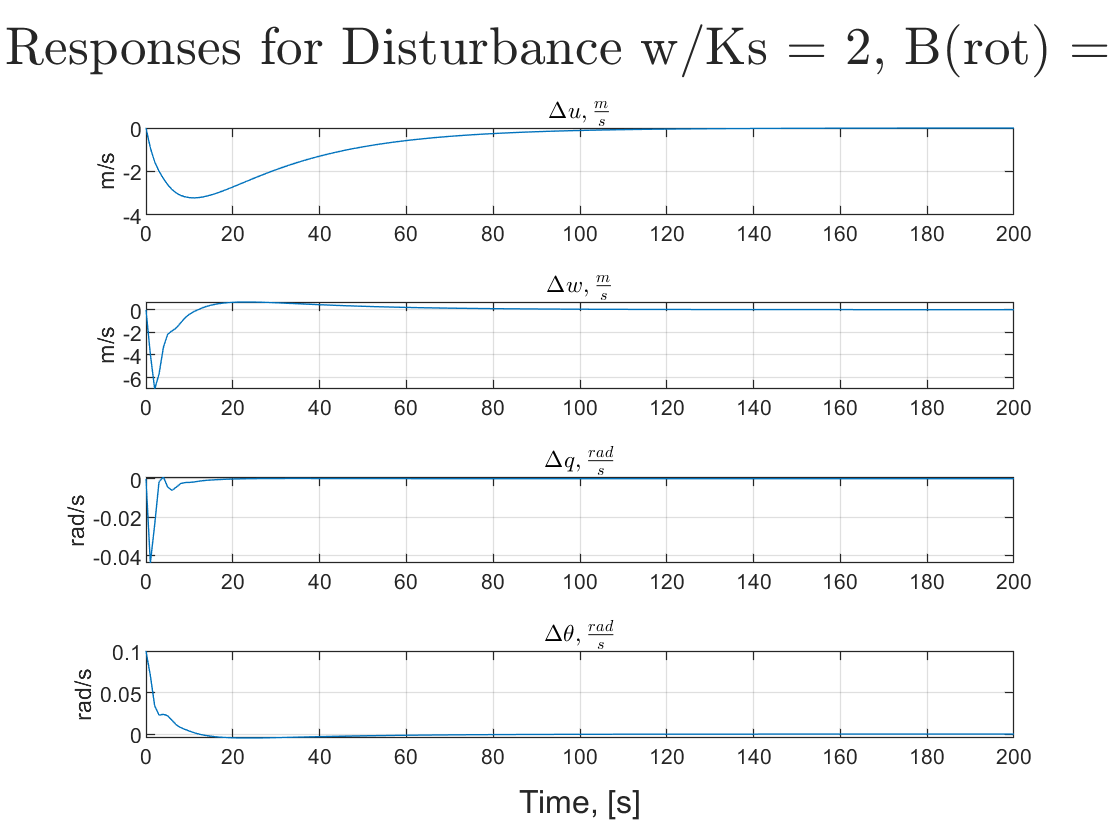

B(1:2, :) = 0; % Setting rotational terms in B to 0
 
[t, y] = ode45(@(t, y) AirplaneLinearized(t, y, A), tSpan, initial);
 
plutter(t, y, 'Disturbance w/Ks = 2, B(rot) = 0');

% See the above Comment for a better plot